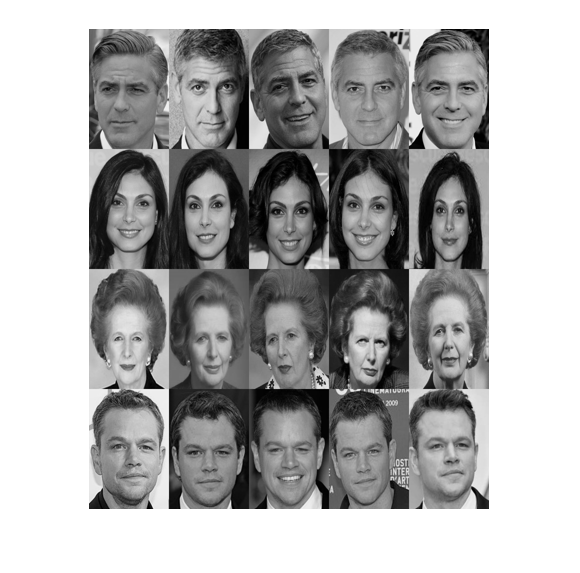

clc
clear
close all
original = imresize(imread('imagematrix.png'),[480,400]);
imshow(original);

[rows , cols] = size(original)

rows = 480

cols = 400

## Separar las imágenes

nfotos = 5;
nfamosos = 4;

fam = 1;
fam1 = matriz_a_eq(nfotos, nfamosos, rows , cols, fam, original);%prueba con equalizacion

fam = 2;
fam2 = matriz_a(nfotos, nfamosos, rows , cols, fam, original);

fam = 3;
fam3 = matriz_a(nfotos, nfamosos, rows , cols, fam, original);

fam = 4;
fam4 = matriz_a(nfotos, nfamosos, rows , cols, fam, original);

## Cálculo de la matriz transpuesta

A1 = transpose(fam1);
A2 = transpose(fam2);
A3 = transpose(fam3);
A4 = transpose(fam4);

## Cálcular C ( A.t * A)

C1 = A1 * fam1;
C2 = A2 * fam2;
C3 = A3 * fam3;
C4 = A4 * fam4;

## EigenValues

[V1,D1] = eigs(C1,20);

## Reconstrucción de las imágenes del EigenVector

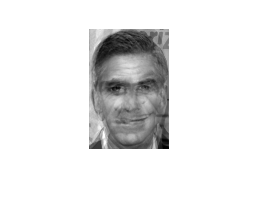

mat1 = zeros(120,80,20);
for i = 1:20
    image = transpose(reshape(V1(:,i),[80,120]));
    mat1(:,:,i) = image;
end

imshow(mat1(:,:,1),[])

## Imágen de prueba

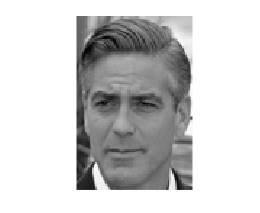

%test_img = double(rgb2gray(imresize(imread('streep_test.jpg'),[120,80])));
test_img = double(original(1:120,1:80));
imshow(test_img,[])

test_v = reshape(transpose(test_img),[1,120*80]);

p = test_v * V1;

X = V1 * transpose(p);

image_r = transpose(reshape(X,[80,120]));
imshow(image_r,[])

## Calcular el error

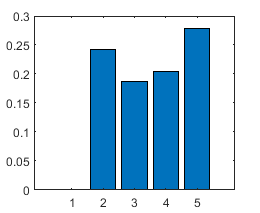

errors = calcular_error(fam1, V1, test_v);
bar(errors)

mean(errors)

ans = 0.1825

## Imágen de prueba equalización

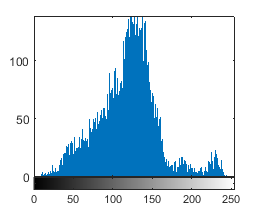

test_img = original(1:120,1:80);

[counts,binLocations] = imhist(test_img);
imhist(test_img);

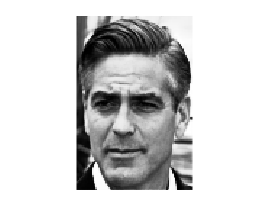



[s,image_t] = equalization(test_img,counts);

imshow(image_t)

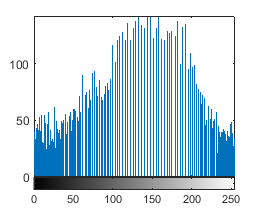

imhist(image_t)

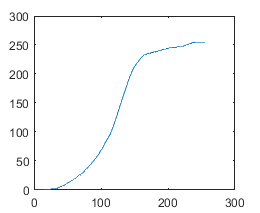

counts_s = imhist(image_t);
plot(s)


test_img = double(original(1:120,1:80));
imshow(test_img,[])

test_v = reshape(transpose(double(image_t)),[1,120*80]);

p = test_v * V1;

X = V1 * transpose(p);

image_r = transpose(reshape(X,[80,120]));
imshow(image_r,[])

## Calcular el error

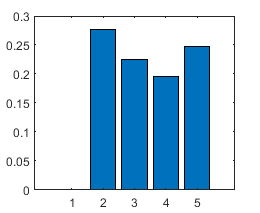

errors1 = calcular_error(fam1, V1, test_v);
bar(errors1)

mean(errors1)

ans = 0.1889

## Funciones 

function fam = matriz_a(nfotos, nfamosos, rows , cols, nfam, original)
    fam = zeros(nfotos,120*80);
    for i = 1:nfotos
        min_col = (cols/nfotos)*(i-1)+1;
        max_col = (cols/nfotos)*i;
        min_row = (rows/nfamosos)*(nfam-1)+1;
        max_row = (rows/nfamosos)*nfam;
        fam(i,:) = reshape(transpose(original(min_row:max_row,min_col:max_col)),[1,120*80]);
        %imshow(original(min_row:max_row,min_col:max_col))
    end
end

function fam = matriz_a_eq(nfotos, nfamosos, rows , cols, nfam, original)
    fam = zeros(nfotos,120*80);
    for i = 1:nfotos
        min_col = (cols/nfotos)*(i-1)+1;
        max_col = (cols/nfotos)*i;
        min_row = (rows/nfamosos)*(nfam-1)+1;
        max_row = (rows/nfamosos)*nfam;
        image = original(min_row:max_row,min_col:max_col);
        counts = imhist(image);
        [s,image_t] = equalization(image, counts);
        fam(i,:) = reshape(transpose(double(image_t)),[1,120*80]);
        %imshow(original(min_row:max_row,min_col:max_col))
    end
end

function errors = calcular_error(fam1, V1, test_v)%modificar con un for con el numero de fotos
    error1 = abs( fam1(1,:)* V1 - test_v*V1)/abs(fam1(1,:)* V1);
    error2 = abs( fam1(2,:)* V1 - test_v*V1)/abs(fam1(2,:)* V1);
    error3 = abs( fam1(3,:)* V1 - test_v*V1)/abs(fam1(3,:)* V1);
    error4 = abs( fam1(4,:)* V1 - test_v*V1)/abs(fam1(4,:)* V1);
    error5 = abs( fam1(5,:)* V1 - test_v*V1)/abs(fam1(5,:)* V1);
    
    errors = [error1,error2,error3,error4,error5];
end

function [s,image_t] = equalization(test_img, counts)
    [m,n] = size(test_img);
    image_t = zeros(m,n,'uint8');
    
    L = 256;
    s = [];
    prob = [];
    
    for j=1:L
        probk = (counts(j)/(m*n));
        prob = [prob, probk];
    end
    
    for k=0:L-1
        sk = 0;
        for j=1:k
            sk = sk + (L-1)*prob(j);
        end
        sk = round(sk);
        s = [s, sk];
    end
    
    for k=0:L-1
        for i=1:m
            for j=1:n        
                if test_img(i,j) == k
                    image_t(i,j) = s(k+1);
                end
            end
        end
    end
end